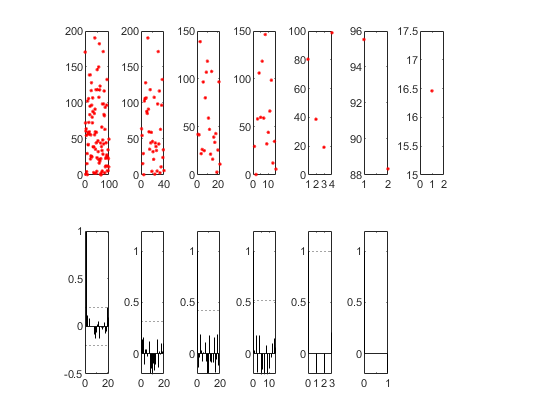

Error using autocorr (line 188)
Number of MA lags must be 
less than number of ACF lags.

clear all;
close all;

fin = fopen('cpu.dat','r');
data = fscanf(fin,'%f');
fclose(fin);

subplot(2,8,1);
plot(data,'.r');
[acf,lags,bounds] = autocorr(data);
subplot(2,8,9);
s = stem(acf,'k');
set(s,'Marker','None');
hold on
yline(bounds(1),':k');
hold on
yline(bounds(2),':k');
hold off

p1 = 2;
for j=2:8
    p = 1/p1;
    clear data_new;
    data_new = [];
    for i=1:length(data)
        brv = binornd(1,p);
        if brv==1 %success
            data_new(end+1) = data(i);
        end
    end
    subplot(2,8,j);
    plot(data_new,'.r');
    [acf,lags,bounds] = autocorr(data_new);
    subplot(2,8,8+j);
    s = stem(lags,acf,'k');
    if j<8
        ylim([-0.2 1.2]);
    else
        ylim([-0.4 1]);
    end
    set(s,'Marker','None');
    hold on
    yline(bounds(1),':k');
    hold on
    yline(bounds(2),':k');
    hold off
    if j<8
        p1 = p1*2;
    end
end